## 2.3.

%dois componentes 1 e 2
p1 = 0.2/100 ;%prob defeito
p2 = 0.5/100 ;
p3 = 1/100;
N = 1e6;

### 1.

####     a) Pelo menos 1 defeito numa caixa

n = 8;

defeitos = 0;
for i = 1:N
    for j = 1:n
        if rand < p1 || rand < p2 || rand < p3
            defeitos = defeitos + 1;
            break
        end
    end
end
p_a = defeitos/N;
fprintf('Probabilidade pelo menos 1 defeito em 8 = %.4f', p_a);

Probabilidade pelo menos 1 defeito em 8 = 0.1276

####     b) Média de brinquedos defeituosos devido à montagem 

total_defeito_montagem = 0;
caixas_defeituosas=0;
for i = 1:N
    defeito = false;
    count_defeitos_montagem = 0;
    for j = 1:n
        defeito_componente = rand < p1 || rand < p2;
        defeito_montagem = rand < p3;

        if defeito_montagem && ~defeito_componente
            count_defeitos_montagem = count_defeitos_montagem + 1;
        end
        if defeito_componente || defeito_montagem
            defeito = true;
        end
    end
    if defeito
        caixas_defeituosas = caixas_defeituosas + 1;
        total_defeito_montagem = total_defeito_montagem +count_defeitos_montagem;
    end
end

media_montagem = total_defeito_montagem/caixas_defeituosas;
fprintf('Número médio de defeitos por montagem é %.3f', media_montagem);

Número médio de defeitos por montagem é 0.625

### 2.

    a)

n = 8;

sem_defeitos = 0;
for i = 1:N
    defeito = false;
    for j = 1:n
        if rand < p1 || rand < p2 || rand < p3
            defeito = true;
            break
        end
    end
    if ~defeito
        sem_defeitos = sem_defeitos + 1;
    end
end
p_b = sem_defeitos/N;
fprintf('Probabilidade não ter defeitos em 8 = %.4f', p_b);

Probabilidade não ter defeitos em 8 = 0.8721

fprintf('1-P(A) = %.4f', 1-p_a);

1-P(A) = 0.8724

%obvio que B = 1-A

    b)

prob_b_t = ((1-p1)*(1-p2)*(1-p3))^n;
fprintf('Probabilidade teórica de B = %.4f', prob_b_t);

Probabilidade teórica de B = 0.8724

   c)

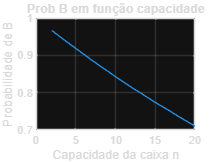

array_b = zeros(1,18);
index = 1;
for n = 2:20
    sem_defeitos = 0;
    for i = 1:N
        defeito = false;
        for j = 1:n
            if rand < p1 || rand < p2 || rand < p3
                defeito = true;
                break
            end
        end
        if ~defeito
            sem_defeitos = sem_defeitos + 1;
        end
    end
    array_b(index) = sem_defeitos/N;
    index = index + 1;
end

plot(2:20, array_b);
grid on;
title('Prob B em função capacidade');
xlabel('Capacidade da caixa n');
ylabel('Probabilidade de B');

  d) 6 bolas

## 3.Variável aleatória X, número de defeitos numa caixa

    a)

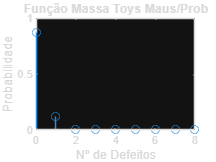

n = 8;
amostral = 0:n;
index = 1; 
defeitos_array = zeros(1,n+1);
for i = 1:N
    defeitos = 1;    
    for j = 1:n    
        if rand < p1 || rand < p2 || rand < p3
            defeitos = defeitos + 1;
        end
    end
    defeitos_array(defeitos) = defeitos_array(defeitos)+1;
end
probabilidades = defeitos_array/N;

stem(0:n,probabilidades);
title('Função Massa Toys Maus/Prob');
xlabel('Nº de Defeitos');
ylabel('Probabilidade');

    b)

fprintf('A probabilidade de X >=2 = %.4f', sum(probabilidades(3:n+1)));

A probabilidade de X >=2 = 0.0076

c)

valor_esperado = sum(amostral .* probabilidades);
variancia = sum((amostral - valor_esperado).^2 .* probabilidades);
desvio_padrao = sqrt(variancia);
fprintf('O valor esperado é %.4f \nA variância é %.4f \nO desvio padrão é %.4f' ,valor_esperado, variancia, desvio_padrao)

O valor esperado é 0.1354 
A variância é 0.1334 
O desvio padrão é 0.3652

d) está noutro file

## 4.

n = 20;
probabilidade_perfect = 0.9;
p1 = 0.2/100 ;%prob defeito
p2 = 0.5/100 ;
p3 = 0.1/100;
N = 1e6;

    a)

m = 1;

testadas= 0;
for i = 1:N
    defeito = false;
    matrix = zeros(n,N);
    for j = 1:n
        if rand < p1 || rand < p2 || rand < p3
            matrix(j,i) = 1;    
        end
    end

    perm = randperm(height(matrix));
    troca = matrix(perm,i);

    for k = 1:m
        if troca(k) == 1
            defeito = true;
        end
    end

    if ~defeito
        testadas = testadas +1;
    end
end

prob_comercilzada = testadas/N;

fprintf('A probabilidade de comercializar uma caixa com m=1 = %.4f', prob_comercilzada);

A probabilidade de comercializar uma caixa com m=1 = 0.9920

   b)

m = 1;
prob_comerciavel = 0;
while prob_comerciavel <= probabilidade_perfect
    if m == 20
        break;
    end
    comercializadas = 0;
    actually_boas = 0;
    for i = 1:N
        
        matrix = zeros(n,1);

        for j = 1:n
            if rand < p1 || rand < p2 || rand < p3
                matrix(j) = 1;
                break;
            end
        end
    
        amostra = matrix(randperm(n,m));
    
        if ~any(amostra)
            comercializadas = comercializadas +1;
            if ~any(matrix)
                actually_boas = actually_boas +1;
            end
        end
    end
    
    prob_comerciavel = actually_boas/comercializadas;
   
    if prob_comerciavel < probabilidade_perfect
        m = m + 1;
    end
end

fprintf('É preciso um m = %d', m);

É preciso um m = 8